# ME 322 Exercise 2 Report - Quarter-car Simulation

**Written by:        **Caiden Bonney - Cal Poly Mechanical Engineering Undergraduate

**Created:**            5/27/2025

**Modified:           **5/27/2025

**Background:    **

This report models the dynamics of a single wheel on a four-wheel vehicle driving over a sinusoidal-shaped road, with varying horizontal velocities. Two approaches were taken: one using block diagrams in Simulink (Exercise 2A), and the other using the state-space representation to solve the system (Exercise 2B). Exercise 2A helped us understand the positional relationships between the components in the system at different horizontal speeds. It also showed how the total force into the vehicle scaled with horizontal velocity. On the other hand, Exercise 2B gave a more comprehensive analysis by examining the system’s response at different oscillatory frequencies. Using the relationship between frequency and horizontal velocity, we determined the resonant speed for the quarter-car. The results from Exercise 2B were compared to those from Exercise 2A by plotting the total force into the vehicle against horizontal displacement. As expected, both models produced identical results, confirming that the two approaches are in agreement.

**Required Files:**

- ME322_Exercise_2_Matlab.mlx

- ME322_Exercise_2_Simulink.slx

- snapshotModel.m

**References:**

        [1]  ME322_2254_Lab_Manual.pdf

## Problem Statement

### Exercise 2A: Block Diagram

Consider Figure 1 which depicts a schematic for a quater-car susepension model meaning it only models one one wheel of a moving vehicle. The wheel is modeled as a spring-damper set, in which $k_t$ represents the spring constant of the wheel, and $b_t$ represents the viscous damping constant for the damping present in the tire. The mass of the wheel and any other components that are not suspended by the suspension are represented by $m_u$ and is referred to as the unsprung mass since these components don't usually leave the road during travel. The car suspension is also modeled as a spring-damper set, in which $k_s$ represents the spring constant of the suspension, and $b_s$ represents the viscous damping constant for the damping resent in the suspension. The mass of the body of the car suspended by the suspension  is represented by $m_c$, and is refered to as the sprung mass. The sprung mass is one quarter of the total mass of the car body since this model only represents a quarter of the total car [1]. 

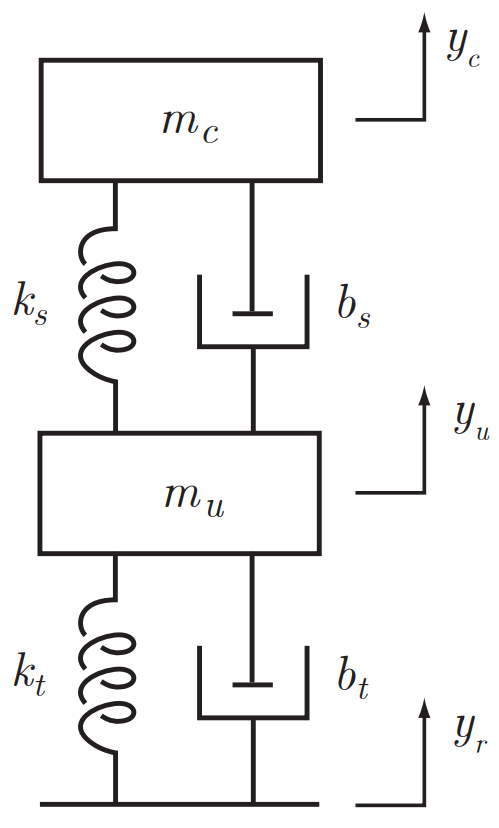

**Figure 1:** Quarter-Car Schematic [1].

The simulation shall assume the system parameters noted in Figure 2 and that the input vertical displacement is defined by,


$$y_r =\textrm{Asin}\left(\frac{2\pi }{\lambda }x_c \right)$$


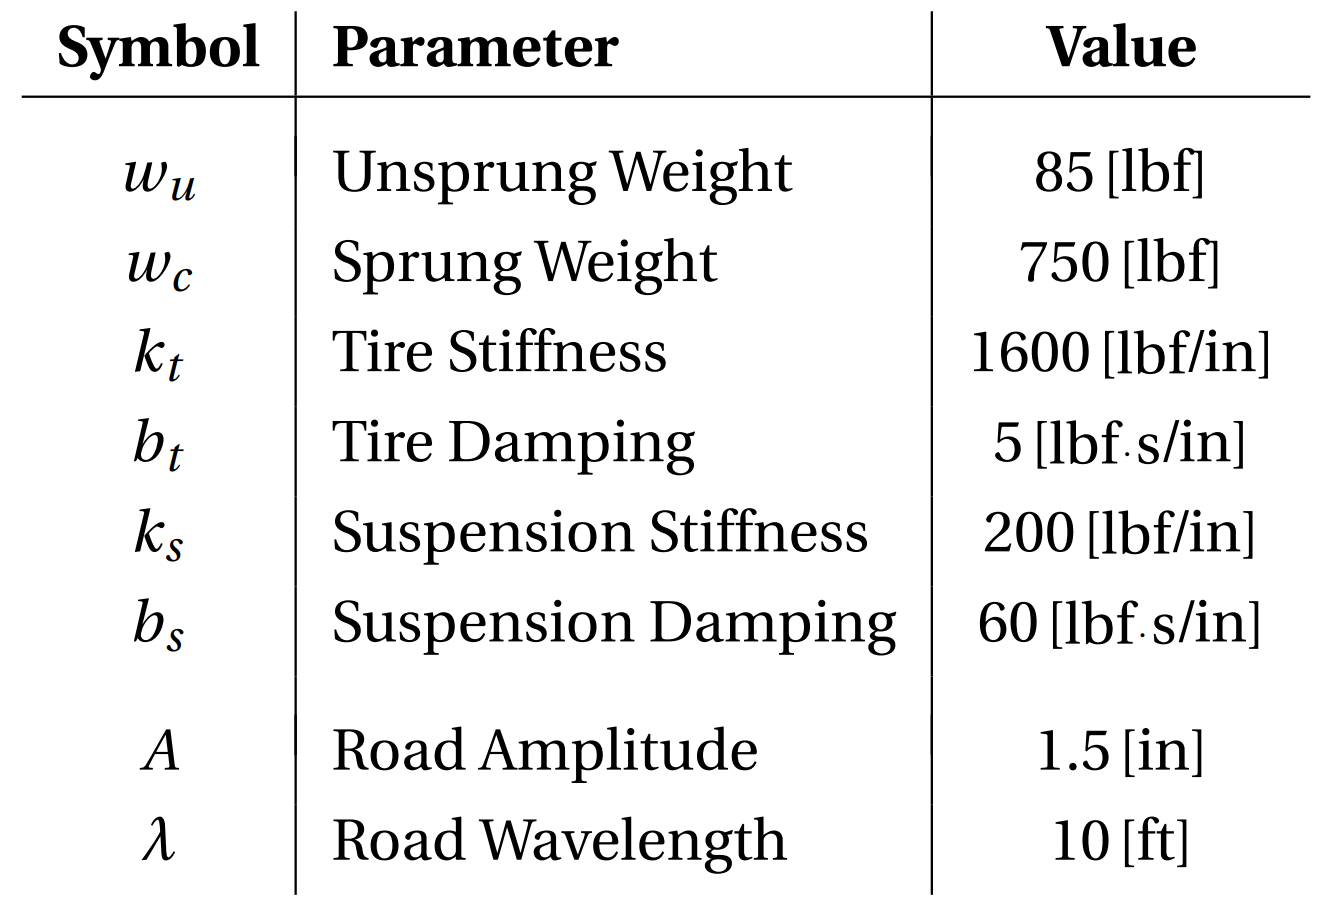

**Figure 2: **Quarter-car system parameters [1].

The simulation will be run at 3 different horizontal velocities which will remain constant for each simulation. Each simulation will be run for a time duration long enough for the vehicle  to travel at least $200\;\left\lbrack \textrm{ft}\right\rbrack$. Figure 3 denotes the output values tracked by the Simulink to be plotted in the Plots - Exercise 2A section. 

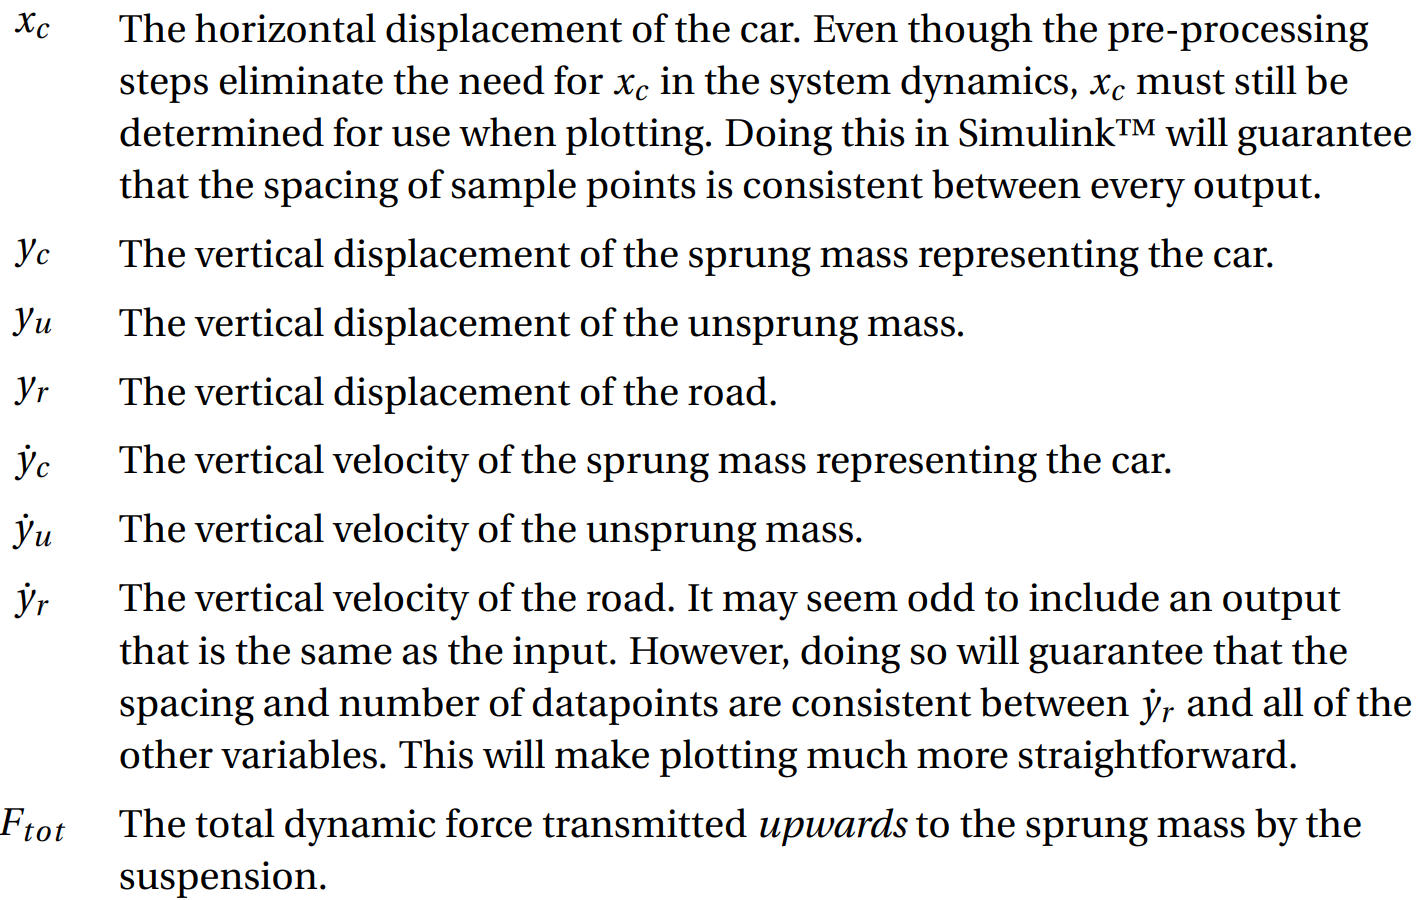

**Figure 3:** Simulink system ouputs [1].

The three different horizontal velocities modeled in the Analysis - Exercise 2A section were ${\dot{x} }_c =5\;\left\lbrack \textrm{MPH}\right\rbrack$, ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$, and ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$in which the vertical displacements are plotted in the Plots - Exercise 2A section. 

Include a plot of the "high speed" simulation of the vertical displacements of the sprung mass, unsprung mass, and road versus the horizontal displacement of the vehicle: $y_c$ , $y_u$, and $y_r$ vs. $x_c$. Then for each of the three speeds plot the vertical displacements of the sprung mass, unsprung mass, and road versus the horizontal displacement of the vehicle: $y_c$ , $y_u$, and $y_r$ vs. $x_c$ as three subplots. Finally, for each of the three speeds plot the total force transmitted to the body of the car versus the horizontal displacement of the vehicle $F_{\textrm{tot}}$ vs. $x_c$.

### Exercise 2B: State-space

Using the equations developed in Exercise 2A fill the augmented state-space matrices found in Figures 4 and 5. 

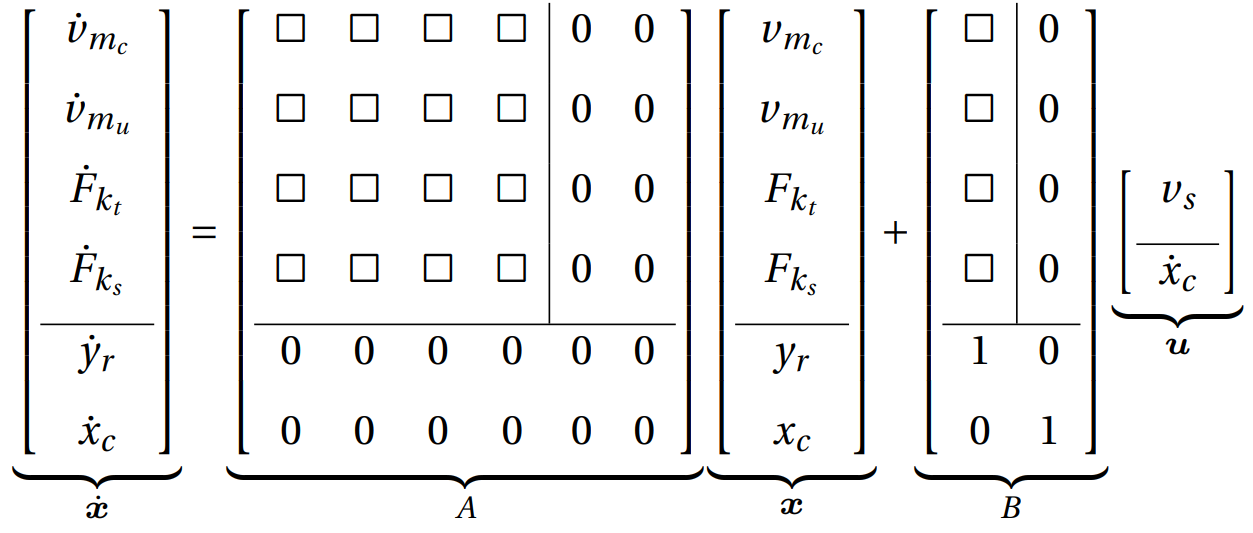

**Figure 4:** Augmented State equation for quarter-car system corresponding to the derivative of the state vector [1].

Figure 4 depicts the unfinished matrix form of the algebraic equation, $\dot{x} =\textrm{Ax}+\textrm{Bu}$ in which $x$ represents the state vector for the system, and $u$ represents the input vector for the system.

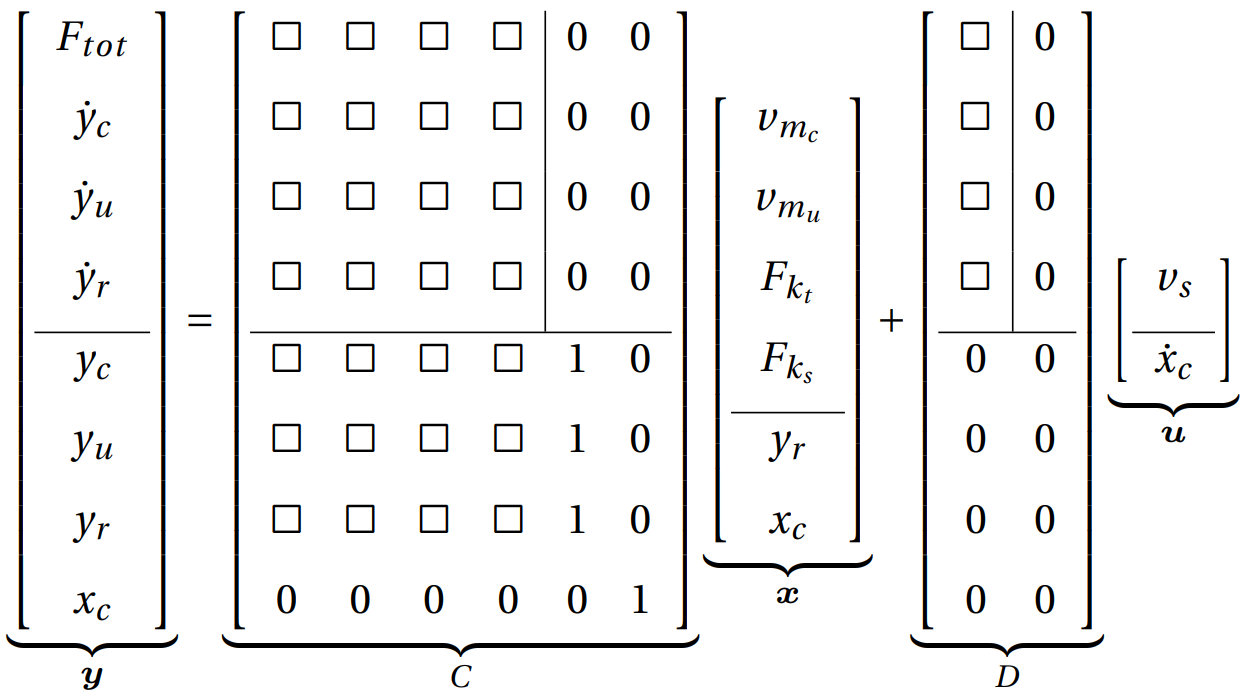

**Figure 5:** Augmented State equation for quarter-car system corresponding to the output matrix [1].

Figure 5 depicts unfinished matrix form of the algebraic equation, $y=\textrm{Cx}+\textrm{Du}$ in which $x$ represents the state vector for the system, and $u$ represents the input vector for the system.

After solving for the matrices  A, B, C, and D shown in Figures 4 and 5, append a "State-Space" block to the Simulink file created during Exercise 2A which references these matrices. Using the "ss" function, create a state-space object to be used to generate the magnitude and phase data for logarithmically defined frequencies using the "bode" function. Then using the "squeeze" function calculate the transmissibility, ${\frac{y_c \;}{y_r }}_{\;}$, and phase shift, $\phi_c -\phi_r$ of the system to be plotted in a semi-log graph against frequency, $\omega =\frac{2\pi \;}{\lambda }\cdot {\dot{x} }_c$. Using this information compare the block diagram results from Exercise 2A to the state-space model results by overlaying simulations results. 

## Hand Calculations

### Exercise 2A

To begin modeling the quarter-car system in Simulink an outline of what the relationship between the system variables is required. This is achieved through the creation of a linear graph as depicted in Figure 6.

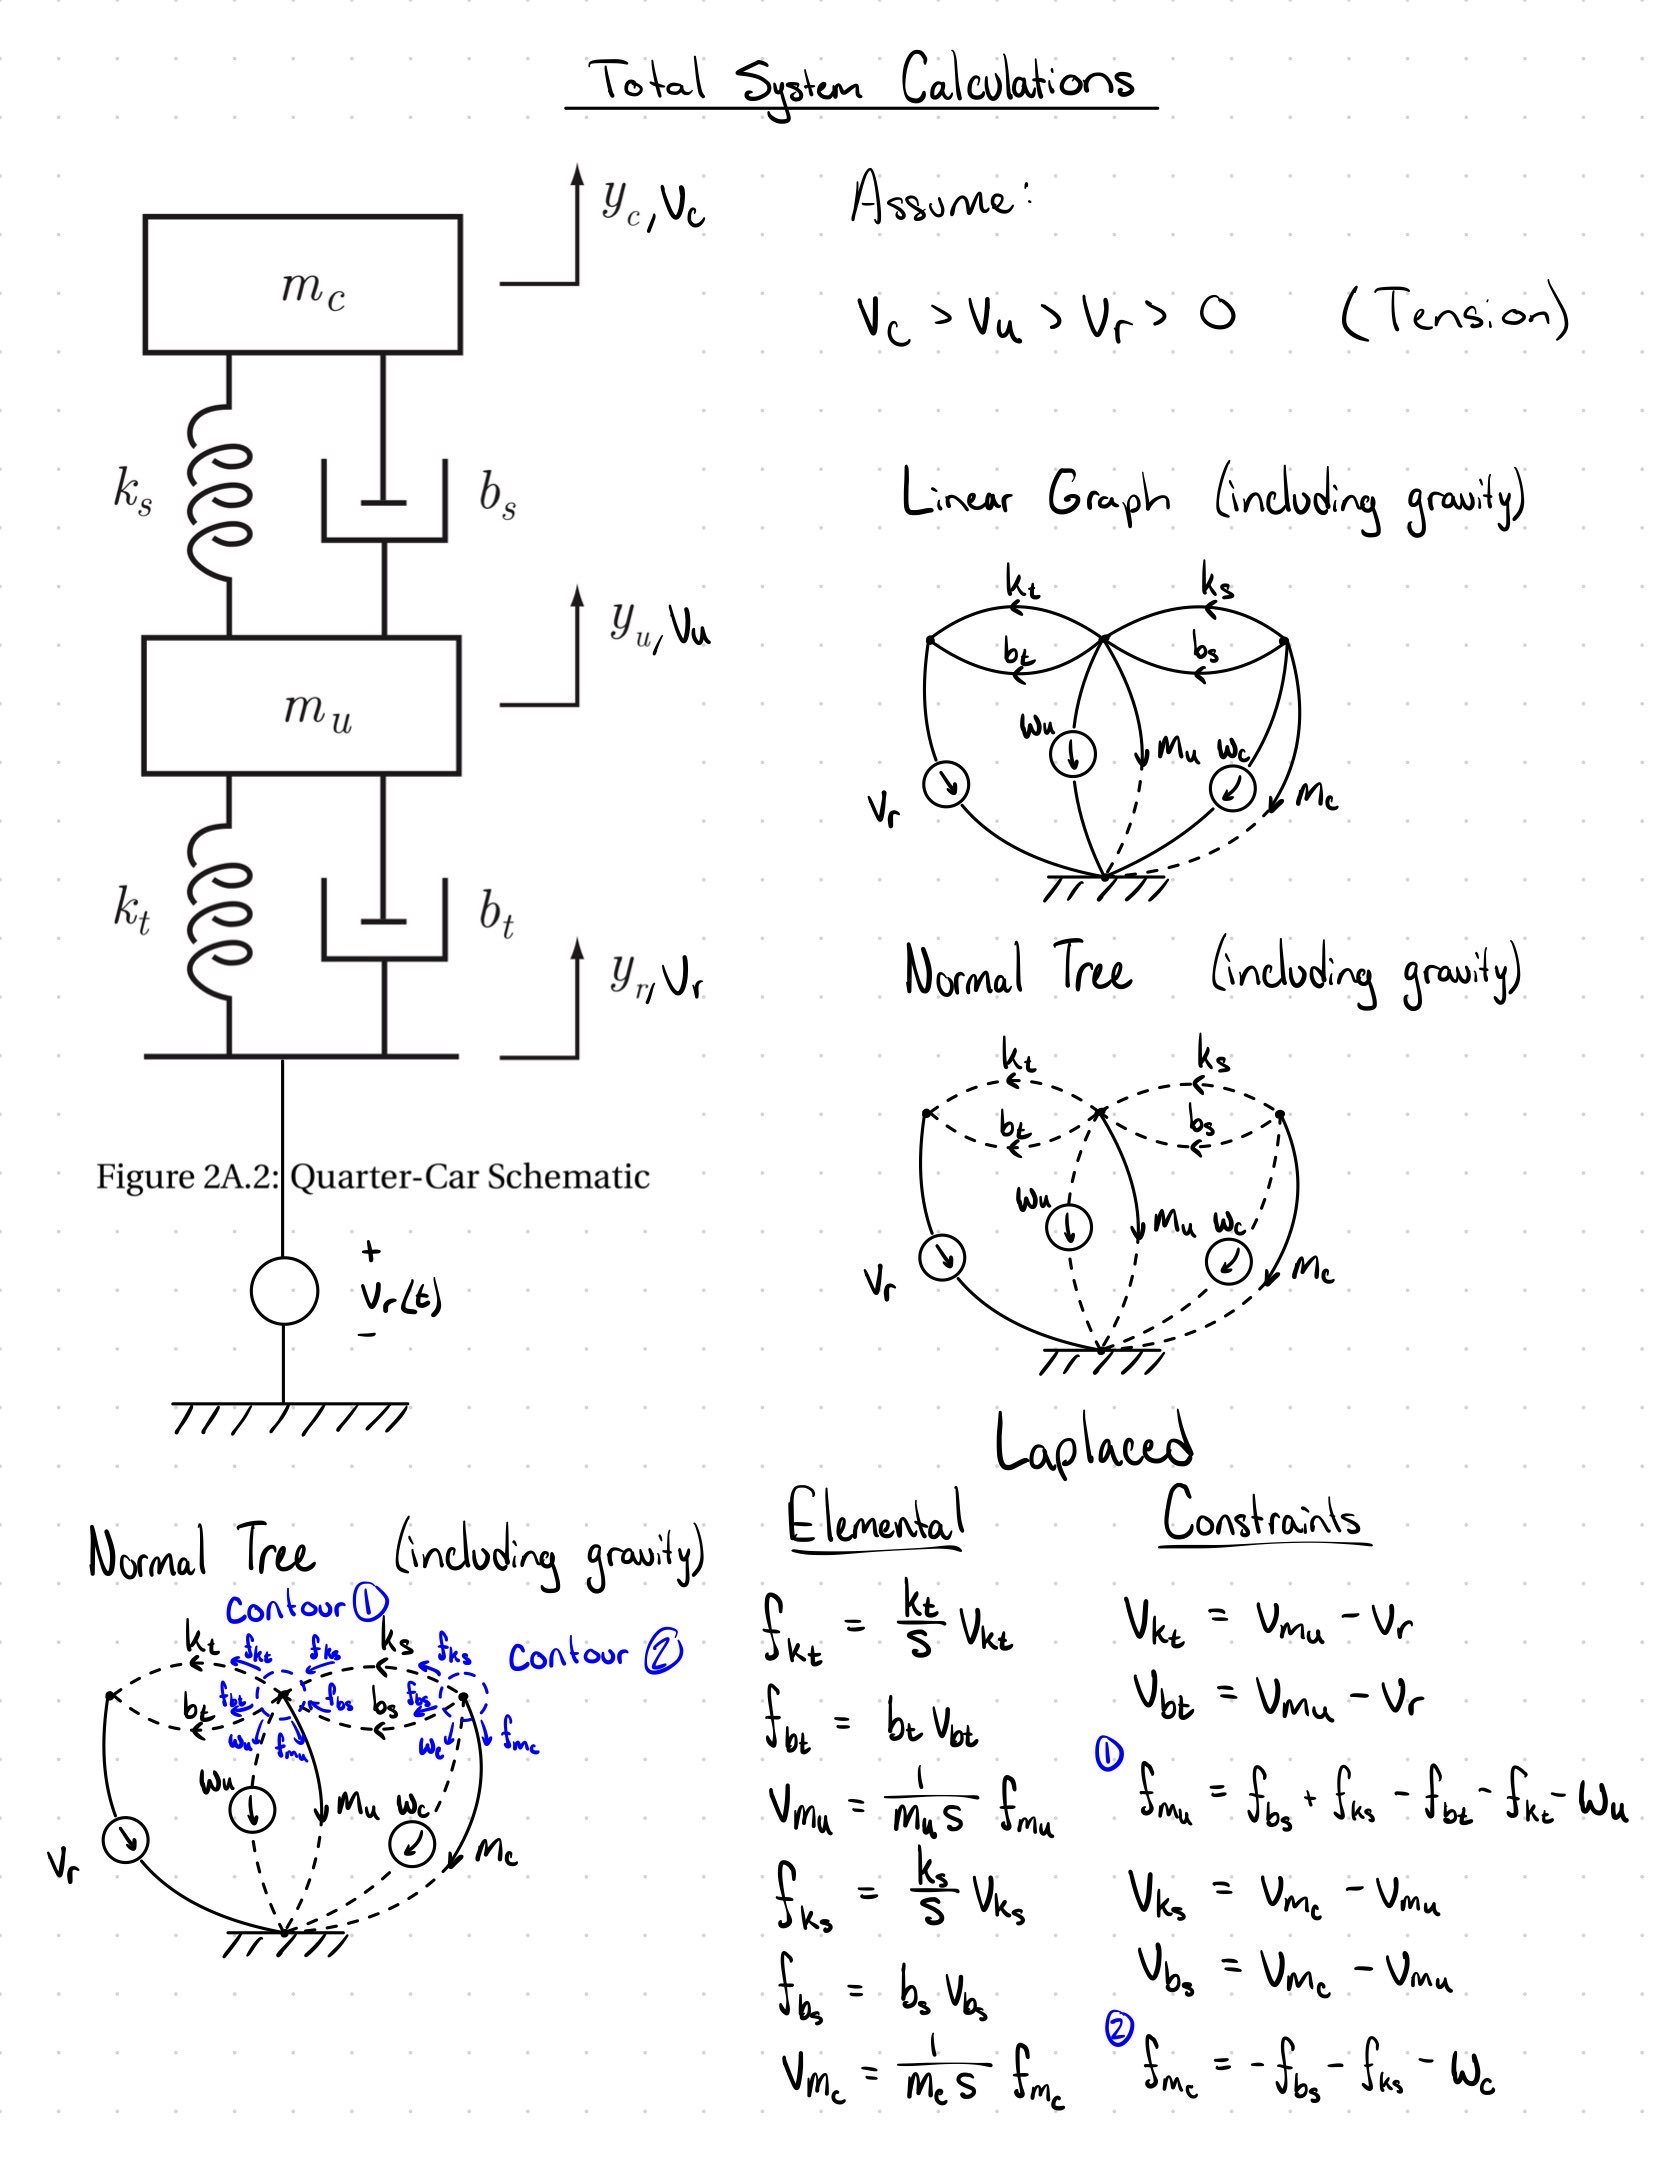

**Figure 6:** Total system calculations for quarter-car system including gravity.

After creating the linear graph a normal tree can be derived. Through the use of this normal tree the system equations are represented by the elemental equations of the individual components, and the constraints  straints modeled in the normal tree. These constraints can be further broken up into compatibility and continuity constraints in which the continuity constraints have the corresponding contour number labeling it with the remaining constraints being compatibility constraints. The compatibility constraints are found by adding in one component missing from the normal tree back in and noting down the loop that is formed from its inclusion. Continuity constraints are found by creating contours which cut through only one link in the normal tree (noted in blue) and tracking all of the input and output forces coming in and out of the contour. 

Figure 6 represents the total system equations including  the static components. Since the objective of this model is to track the dynamic changes that occur when driving over changing terrain the static parts of the model need to be removed. These static components are noted in Figure 7 which models the forces on the masses when there are no dynamic inputs to the system.  

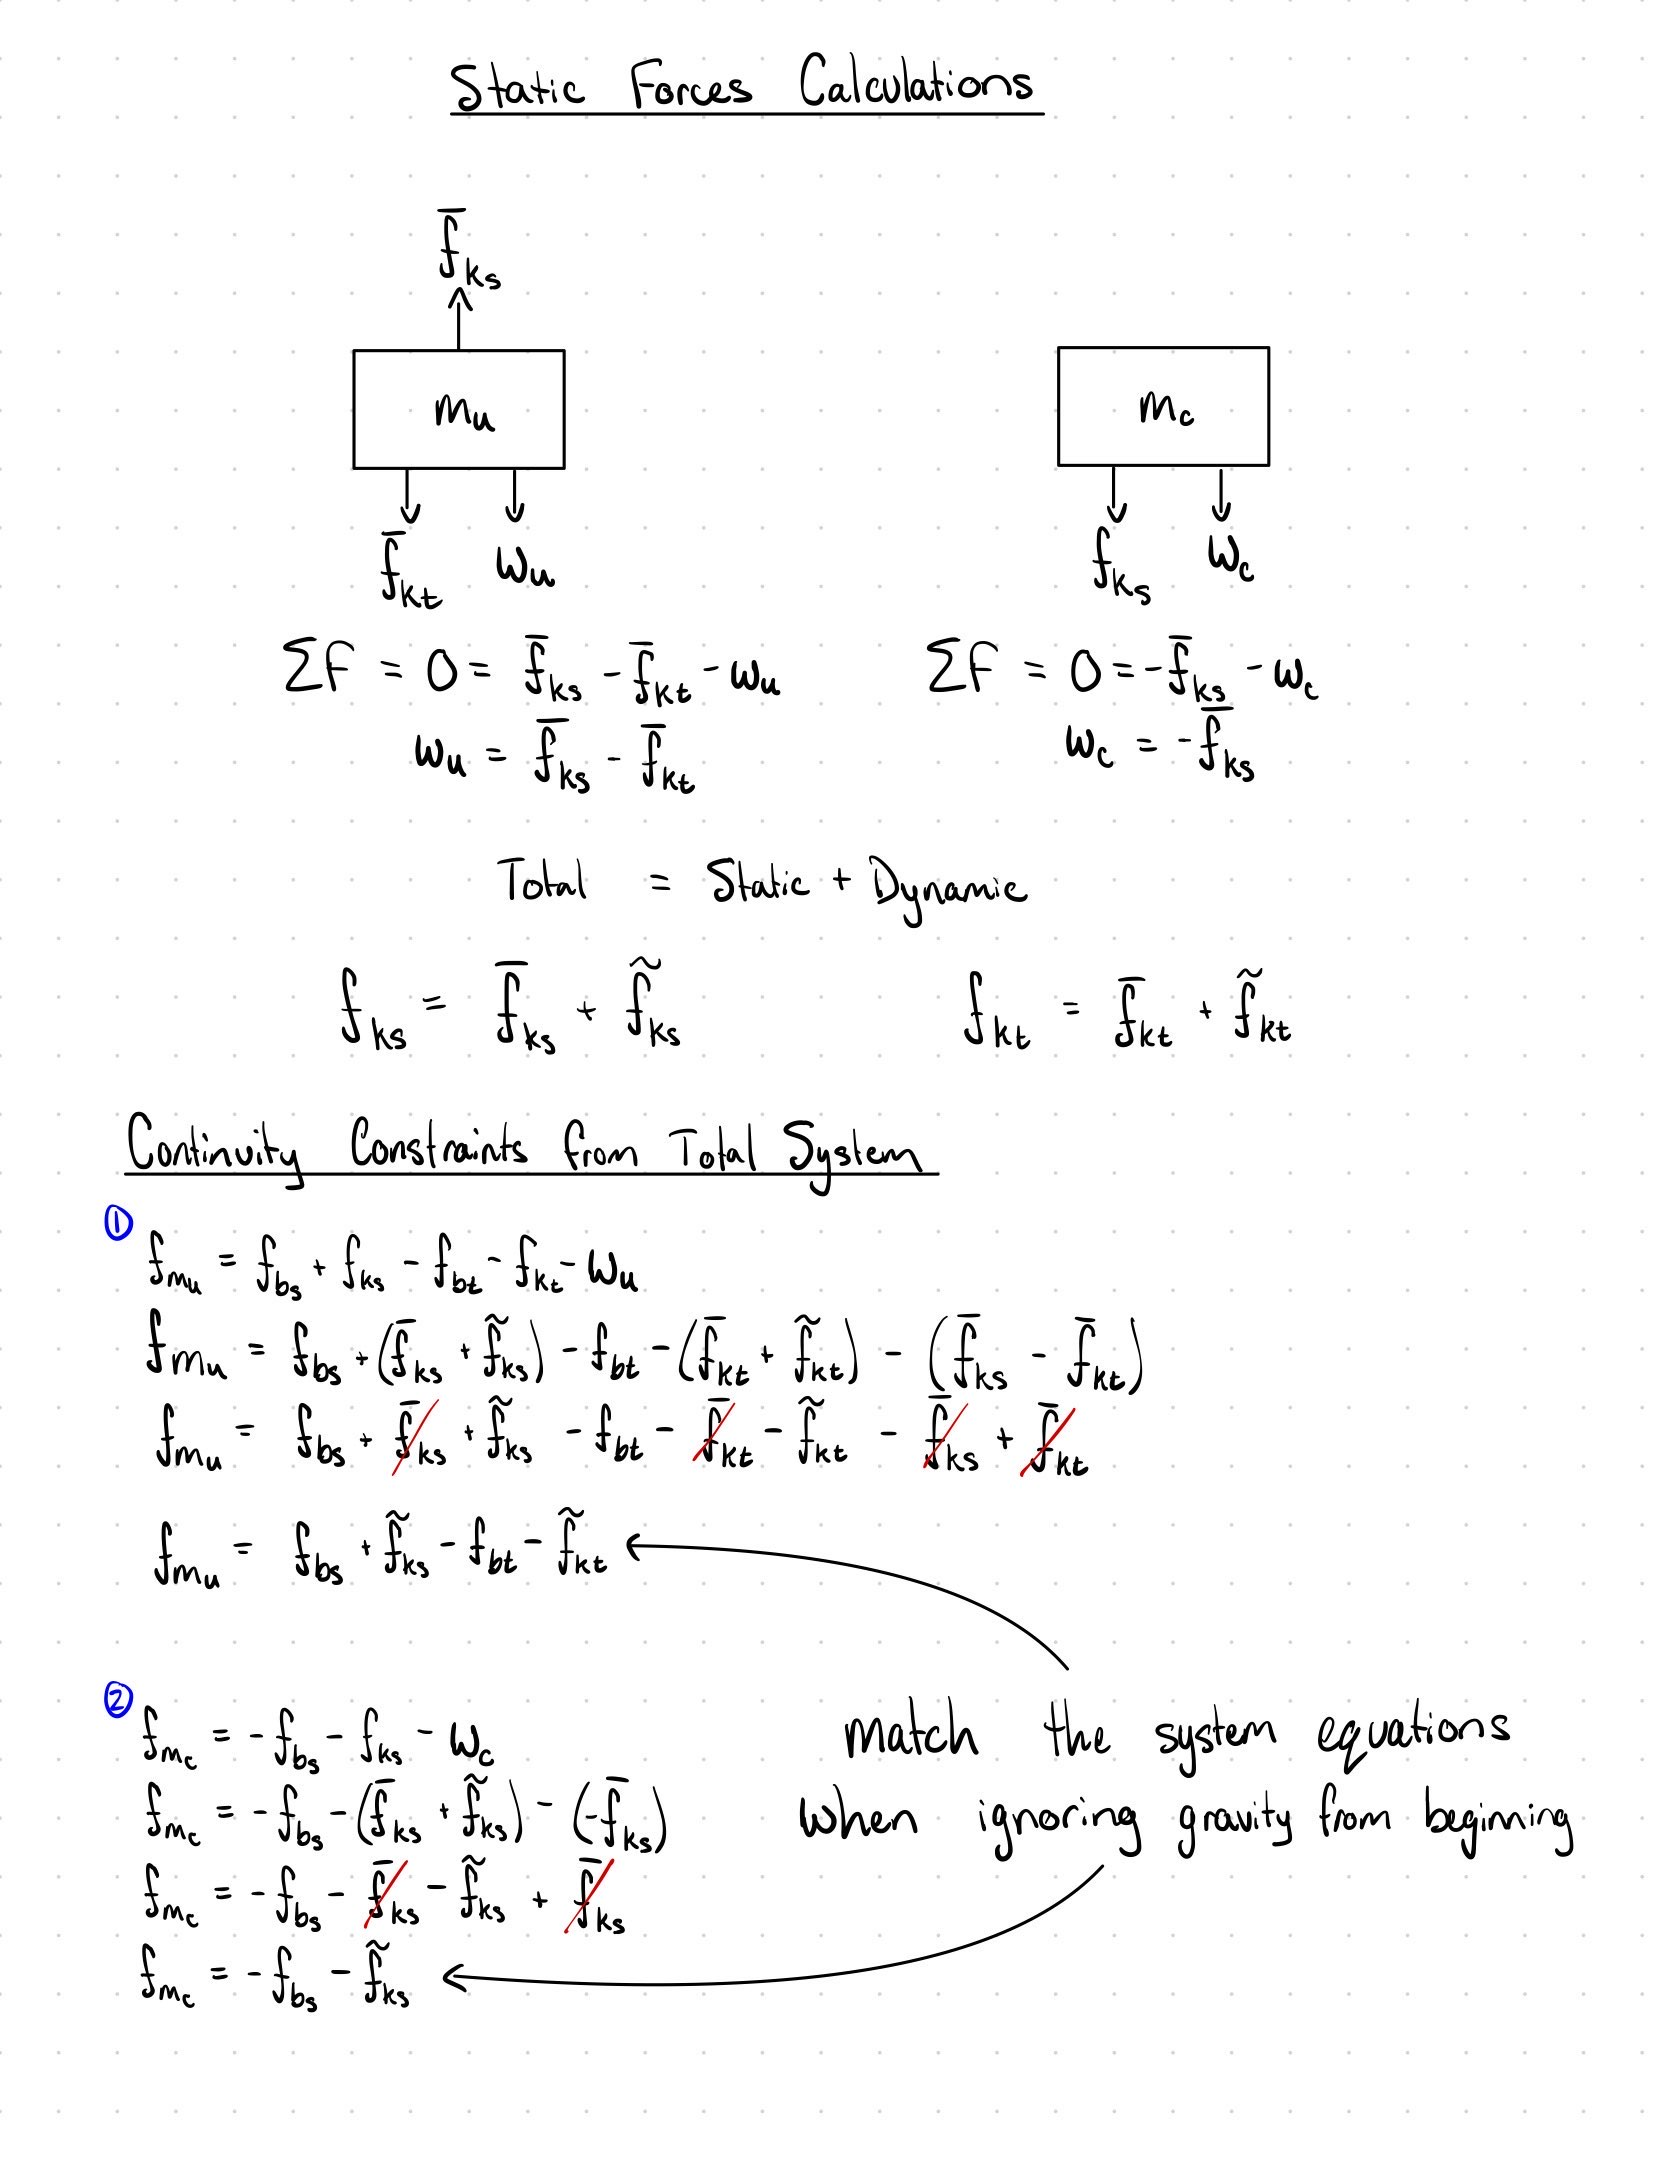

**Figure 7:** Static force calculations for quarter-car system resulting from gravity.

By removing the dynamic inputs to the system there are no forces caused by the dampers or by any input velocity function so the only forces acting upon the masses are the weights corresponding to each mass, and the static tension in each of the springs. Figure 7 also depicts solving for the dynamic system equations by substituting for the weights into the total system equations. Note that the resulting equations look identical to the original equations if the spring forces were to be only the dynamic components and the weights were to be ignored. This is confirmed by remodeling the entire system ignoring the effects of gravity, in Figure 8, to determine whether the same equations can be determined without the need to calculate and remove the static forces simplifying the time for needed for the modeling system. 

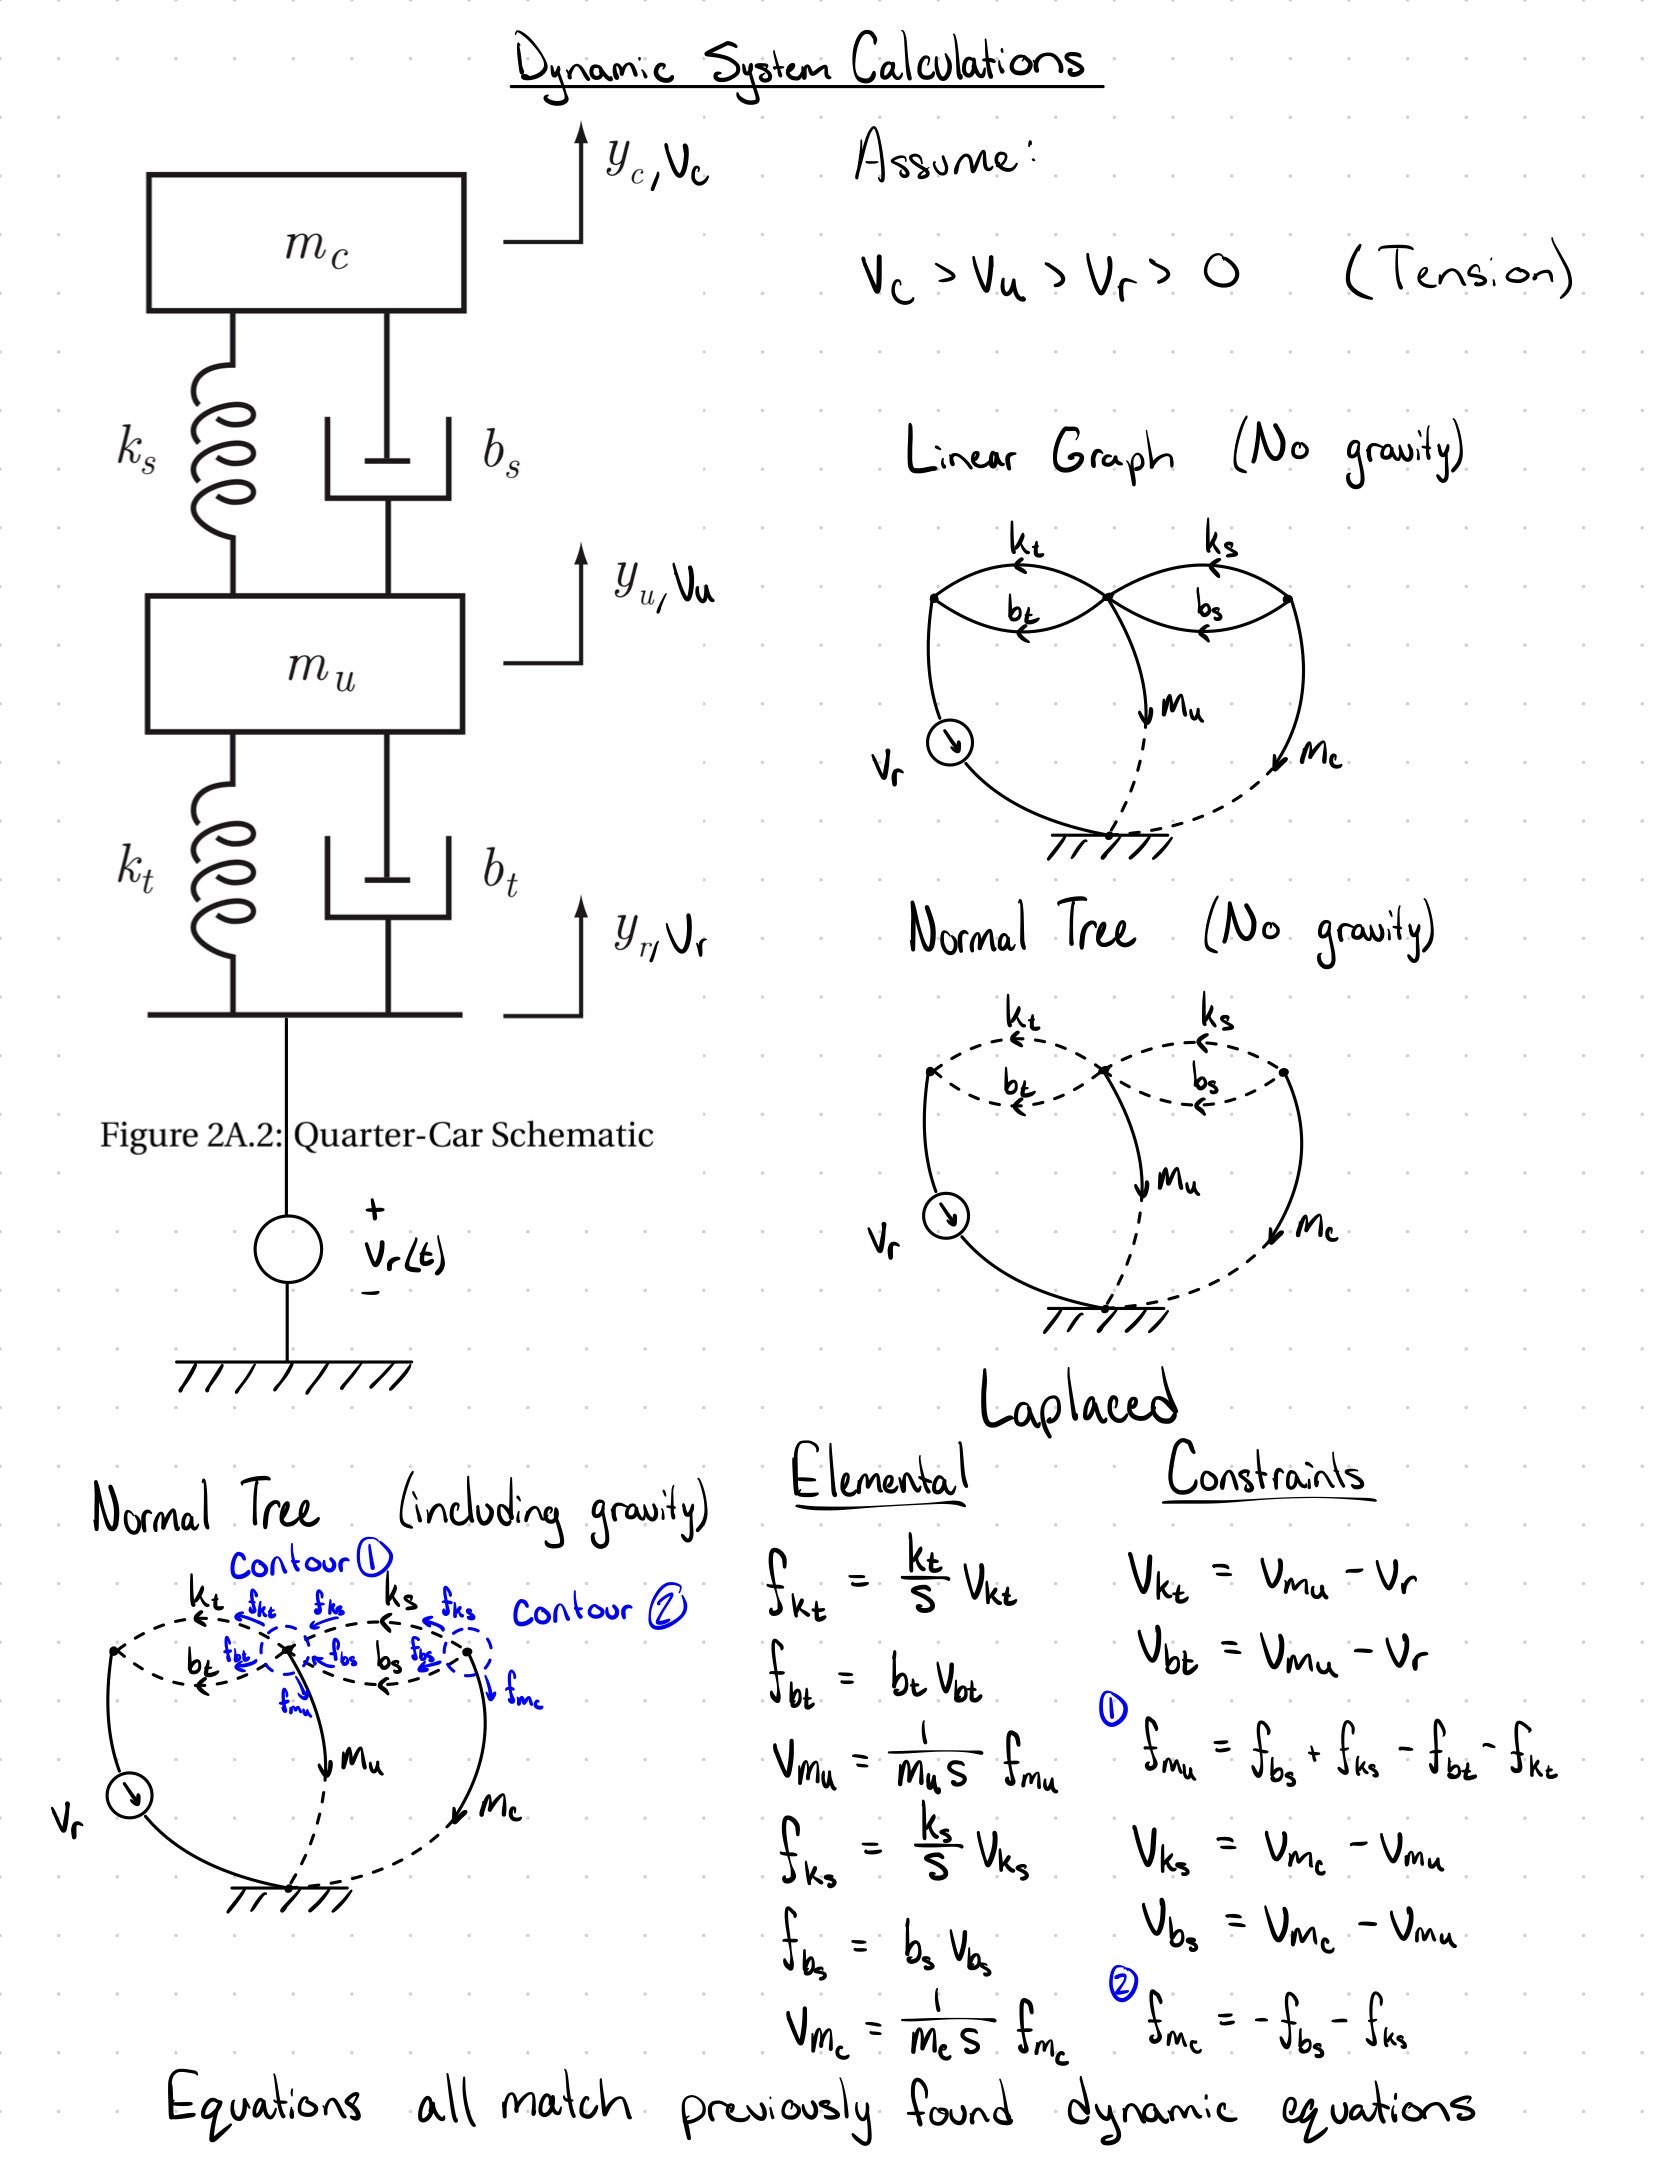

**Figure 8:** Dynamic system calculations for quarter-car system neglecting gravity.

As noted at the bottom of Figure 8 all system equations calculated by neglecting gravity from the start match the previous method of calculating the total response of the system and removing the static components. These calculations confirm that neglecting gravity in this case will result in the dynamic response of the system. 

We require the vertical velocity of the road to be in terms of time and other constant values given the vertical displacement of the road was given in terms of horizontal displacement as depicted at the top of Figure 9. 

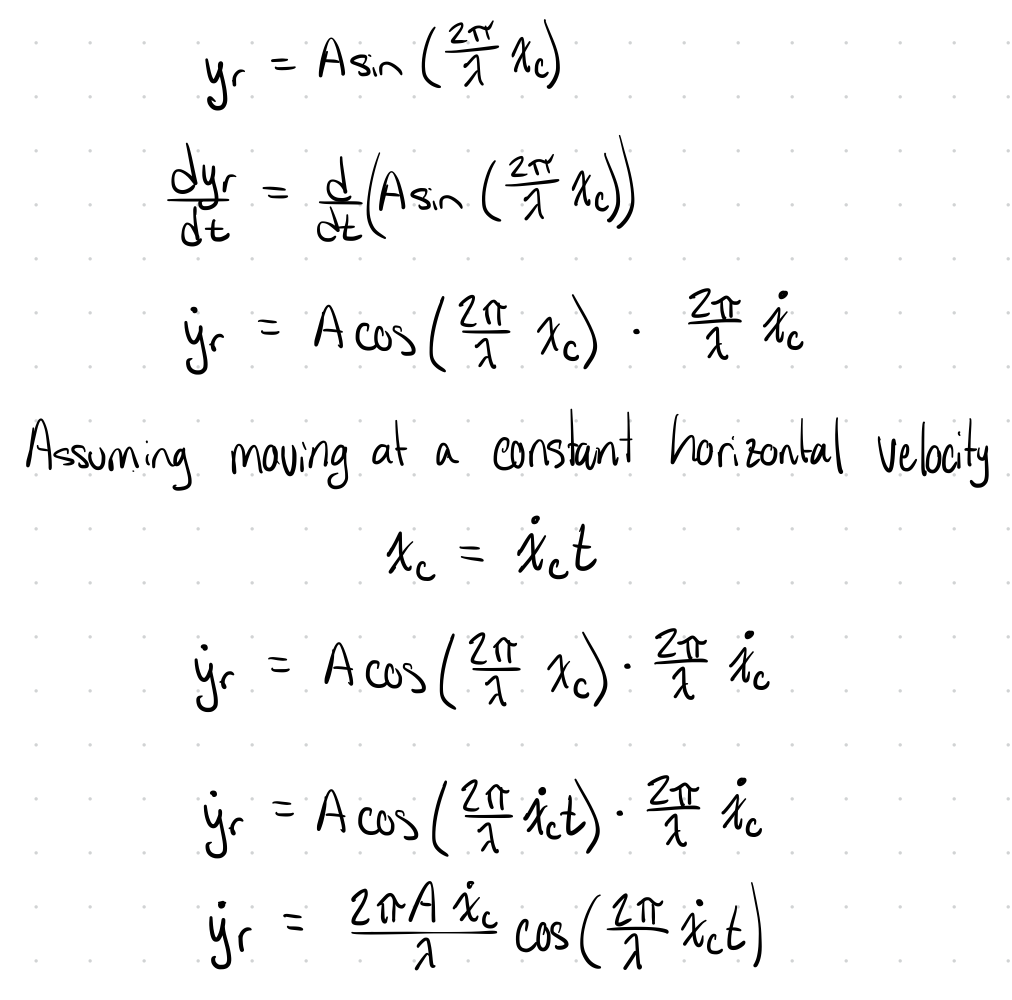

**Figure 8:** Dynamic system calculations for quarter-car system neglecting gravity.

Figure 8 depicts the calculation of the vertical velocity as a function of time and other values that remain constant for the course of the simulation such as the horizontal velocity which is held constant at the three values noted in Problem Statement - Exercise 2A.

### Exercise 2B

Using the system equations found in Figure 8, Figure 10 reiterates these equations before they were Laplaced and the steps taken to fill out the missing matrix values from Figure 4. 

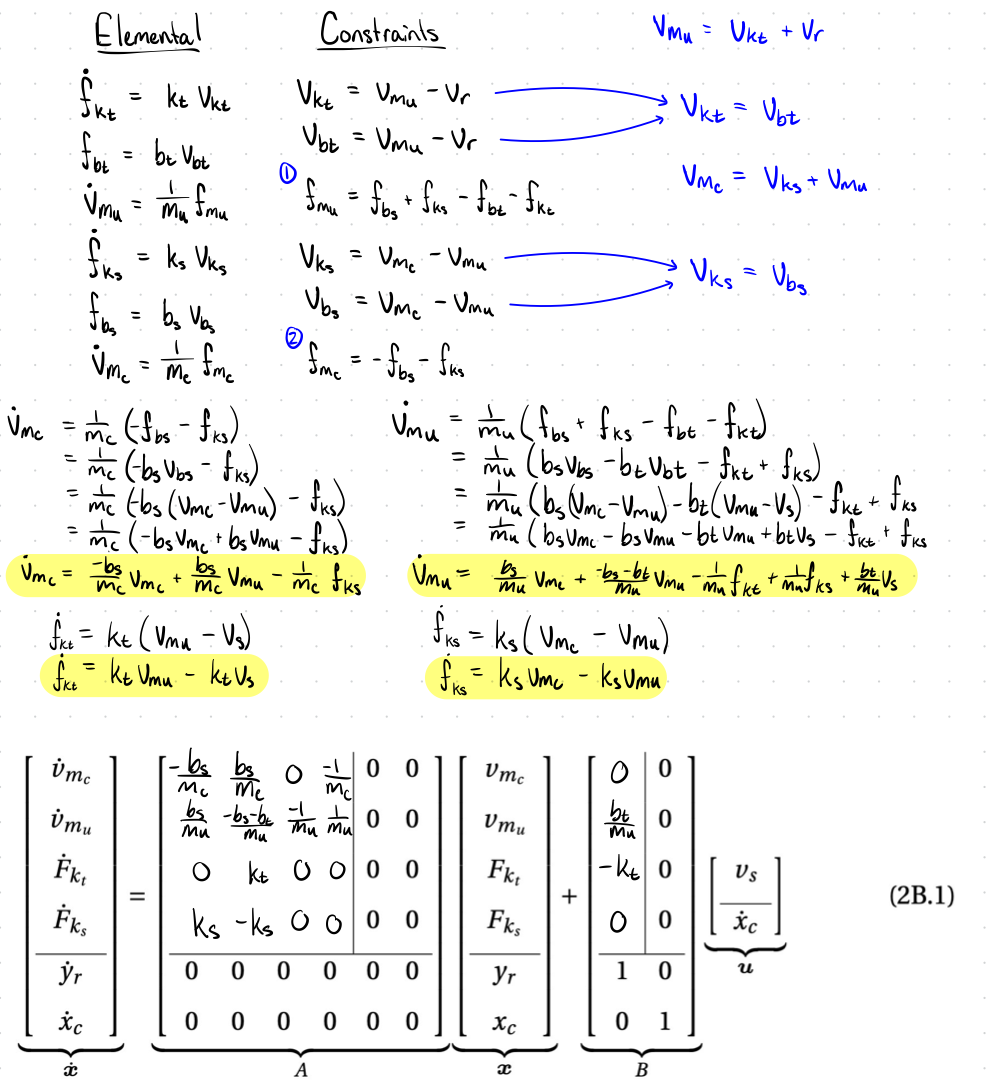

**Figure 10:** Deriving missing matrix values for the state equation $\dot{x} =\textrm{Ax}+\textrm{Bu}$.

Figure 11 depicts the derivation of the missing matrix values for the matrix depicted in Figure 5.

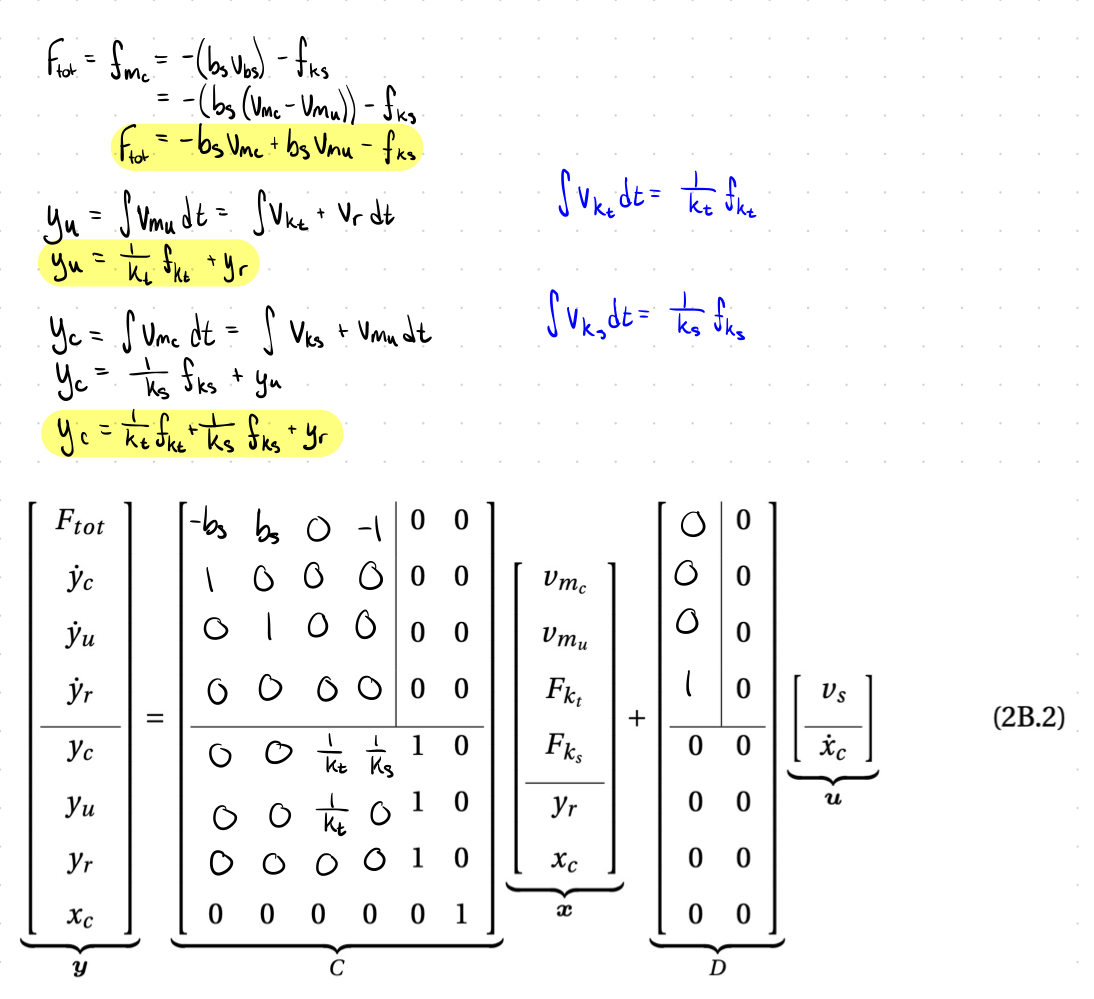

**Figure 11:** Deriving missing matrix values for the state equation $y=\textrm{Cx}+\textrm{Du}$.

From Figures 10 and 11 the matrices A, B, C, and D are now known and ready to be used in the state-space analysis done in Analysis - Exercise 2B.

## Analysis

### Exercise 2A

This section will define simulation parameters needed in the Simulink.

clear; % Clear workspace of previous MATLAB calculations

w_u = 85;               % [lbf] Unsprung Weight
w_c = 750;              % [lbf] Sprung Weight
g = 32.2*12;            % [in/s^2] gravity
m_u = w_u/g;            % [lbf-s^2/in] Unsprung Mass 
m_c = w_c/g;            % [lbf-s^2/in] Sprung Mass
k_t = 1600;             % [lbf/in] Tire Stiffness
b_t = 5;                % [lbf-s/in] Tire Damping
k_s = 200;              % [lbf/in] Suspension Stiffness
b_s = 60;               % [lbf-s/in] Suspension Damping

A_r = 1.5;              % [in] Road Amplitude
lambda_r = 10;          % [ft] Road Wavelength
phase_shift_r = pi()/2; % 90 deg shift to convert sine wave to cosine wave


The following block of code is for Exercise 2B which requires the addition of a state-space block to the Simulink, therefore, matrices A, B, C, and D must be defined before the simulations are run to prevent errors and extraneous simulations.

%     1           2                 3         4         5    6
A = [ -b_s/m_c    b_s/m_c           0         -1/m_c    0    0
      b_s/m_u     (-b_s-b_t)/m_u    -1/m_u    1/m_u     0    0
      0           k_t               0         0         0    0
      k_s         -k_s              0         0         0    0
      0           0                 0         0         0    0
      0           0                 0         0         0    0];

%     1          2
B = [ 0          0
      b_t/m_u    0
      -k_t       0
      0          0
      1          0
      0          1];

%     1       2      3        4        5    6
C = [ -b_s    b_s    0        -1       0    0
      1       0      0        0        0    0
      0       1      0        0        0    0
      0       0      0        0        0    0
      0       0      1/k_t    1/k_s    1    0
      0       0      1/k_t    0        1    0
      0       0      0        0        1    0
      0       0      0        0        0    1];

%     1    2
D = [ 0    0
      0    0
      0    0
      1    0
      0    0
      0    0
      0    0
      0    0]; 

This section of code adjusts ${\dot{x} }_c$ before running the Simulink for the amount of time it takes for the car to travel $200\;\left\lbrack \textrm{ft}\right\rbrack$ since moving the same distance at a faster velocity takes less time, and therefore the simulation time must be adjusted for this. To do this the velocity is converted from miles per hour to feet per second before the total distance traveled of $200\;\left\lbrack \textrm{ft}\right\rbrack$ is divided by this speed. The result of this calculation is the length of time the simulation must run for the car to move a distance of $200\;\left\lbrack \textrm{ft}\right\rbrack$. 

opt = simset('RelTol', 1e-6);       % Adjust resolution of Simulink 
total_dist = 200;                   % Total distance traveled during simulation time frame

xdot_c = 5;                         % [MPH]  Slow speed velocity value
xdot_c = (xdot_c*5280)/(60*60);     % [ft/s] Slow speed velocity value converted from MPH to ft/s 
out_slow = sim("ME322_Exercise_2_Simulink", total_dist/xdot_c, opt); % Slow speed simulation results

Model 'ME322_Exercise_2_Simulink' does not exist.


xdot_c = 35;                        % [MPH]  Medium speed velocity value
xdot_c = (xdot_c*5280)/(60*60);     % [ft/s] Medium speed velocity value converted from MPH to ft/s
out_med = sim("ME322_Exercise_2_Simulink", total_dist/xdot_c, opt); % Medium speed simulation results

xdot_c = 65;                        % [MPH]  Fast speed velocity value
xdot_c = (xdot_c*5280)/(60*60);     % [ft/s] Fast speed velocity value converted from MPH to ft/s 
out_fast = sim("ME322_Exercise_2_Simulink", total_dist/xdot_c, opt); % Fast speed simulation results

### Exercise 2B

This section will create a state-space system object using the matrices A, B, C, and D found in the Hand Calculations - Exericse 2B section and defined in the Analysis - Exercise 2A section. After defining omega logarithmically the "bode" function can be used to calculate the magnitude and phase angle for the state-space system object for each of the different frequencies in omega. Then using the "squeeze" function to find the magnitude ratio's for different inputs to outputs the displacement transmissibility, $\frac{y_c }{y_r }$, between two inputs was calculated as the ratio of the 5th output's magnitude ratio, $\frac{y_c }{{\dot{y} }_r }$, and the 7th output's magnitude ratio, $\frac{y_r }{{\dot{y} }_r }$, since the ratio of these two magnitude, $\left(\frac{y_c }{{\dot{y} }_r }\right)/\left(\frac{y_r }{{\dot{y} }_r }\right)$, is equivalent to the displacement transmissibility, $\frac{y_c }{y_r }$. The maximum value of the transmissibility occurs at resonant frequency. Finally, from this omega the velocity at which resonance occurs can be found and converted to miles per hour. 

% Create a state-space system object
sys = ss(A, B, C, D);
% Generate log spaced data between 10^-1 and 10^3 with 100 steps .
omega = logspace(-1, 3, 100);
% Perform a frequency response and store the output
[mag, phase] = bode(sys, omega);
H_5 = squeeze(mag(5, 1,:)); % Magnitude Ratio y_5/u_1 = y_c/v_r
H_7 = squeeze(mag(7, 1,:)); % Magnitude Ratio y_7/u_1 = y_r/v_r
T = H_5 ./ H_7; % Transmissibility between y_5/y_7 = y_c/y_r
[res_T, res_T_idx] = max(T); % Find resonant frequency by finding the max of the transmissibility
res_freq = omega(res_T_idx); % Using index of max transmissibility to find resonant frequency

% since frequency, omega, corresponds to the omega in A*sin(omega*t) then 
%   omega = (2*pi()*xdot_c)/lambda_r
%   Solving for xdot_c to find the horizontal velocity at resonance occurs
%   xdot_c = (omega*lambda_r)/(2*pi())
res_vel_fps = (res_freq*lambda_r)/(2*pi()); % [ft/s] horizontal velocity at resonant frequency
res_vel_mph = (res_vel_fps*(60*60))/5280;  % [MPH] horizontal velocity at resonant frequency

## Tabular Data

The following code creates a table which tabulates the resonant frequency, $\omega =\frac{2\pi }{\lambda_r }\cdot {\dot{x} }_c$, corresponding horizontal velocity, ${\dot{x} }_c$, at this resonant frequency, and the displacement transmissibility, $\frac{y_c }{y_r }$, at resonant frequency, all found in the Analysis - Exercise 2B section. 

tbl = table(res_freq, res_vel_mph, res_T, 'VariableName', {'Resonant Frequency [rad/s]', 'Resonant Horizontal Velocity [MPH}', 'Displacement Transmissibility [-]'}) 

**Table 1:** System's Resonant Frequency and its corresponding Horizontal Velocity and Displacement Transmissibility.

## Block Diagram

This section uses "snapshotModel" to take a screen capture of the current block model displayed in "ME322_Exercise_2_Simulink". "ME322_Exercise_2_Simulink" contains the block diagram for the Simulink simulation of the quarter-car system and state-space block which references matrices, A, B, C, and D derived in the Hand Calculations - Exercise 2B section.

snapshotModel("ME322_Exercise_2_Simulink");

**Figure 12:** Screenshot of Simulink including the quarter-car system block diagram, and the state-space calculations for comparison in the Plots section.

## Plots

### Exercise 2A

#### Plot 1 - Vertical Displacement versus Horizontal Displacement for "freeway speed" simulation, 65 MPH

The following code plots the vertical displacements$y_{c\;}$, $y_{u\;}$, and $y_r$ with the horizontal displacement, $x_c$, at a constant horizontal velocity ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$.

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
plot(out_fast.x_c, out_fast.y_r, LineWidth=1, DisplayName="Road, $y_{r}$");
hold on
plot(out_fast.x_c, out_fast.y_u, LineWidth=1, DisplayName="Unsprung Mass, $y_{u}$");
plot(out_fast.x_c, out_fast.y_c, LineWidth=1, DisplayName="Sprung Mass, $y_{c}$");
xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
ylabel("Vertical Displacement, y [in]", "Interpreter", "latex");
xlim([0, 35]);
legend('Interpreter', 'latex');
hold off

**Figure 13:** Vertical Displacement of the road $y_r$, unsprung mass $y_u$, and sprung mass, $y_c$, vs. Horizontal Displacement, $x_c$, for ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$

#### Plot 2 - Vertical Displacement versus Horizontal Displacement for All Speeds Simulated, 5, 35, and 65 MPH

The following code plots the vertical displacements$y_{c\;}$, $y_{u\;}$, and $y_r$ with the horizontal displacement, $x_c$, at a three different constant horizontal velocities ${\dot{x} }_c =5\;\left\lbrack \textrm{MPH}\right\rbrack$, ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$, and ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$. The plots illustrate how at lower speeds the sprung and unsprung mass nearly reach the same deflection as the road's bumps are but at higher speeds the sprung and unsprung masses don't deflect as much. This lower deflection at higher speeds is due to how quickly vertical velocity changes from positive to negative allowing less time for the mass to deflect before the opposing side of the bump pulls the mass back opposing the original direction of motion, and therefore, overall decreasing the overall deflection. However, since the unsprung mass's deflection is higher than the deflection of the road for the medium speed case of ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$ it is likely that this speed is near the resonant frequency at which point the resonant response starts to affect the masses leading to larger deflections than the road. The resonant frequency calculated in Analysis - Exericse 2B for the system is roughly $21\;\left\lbrack \textrm{MPH}\right\rbrack$ which is relatively near ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$ when compared to the other speeds simulated. 

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 1000]);
subplot(3,1,1)
    plot(out_slow.x_c, out_slow.y_r, LineWidth=1, DisplayName="Road, $y_{r}$");
    hold on
    plot(out_slow.x_c, out_slow.y_u, LineWidth=1, DisplayName="Unsprung Mass, $y_{u}$");
    plot(out_slow.x_c, out_slow.y_c, LineWidth=1, DisplayName="Sprung Mass, $y_{c}$");
    xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
    ylabel("Vertical Displacement, y [in]", "Interpreter", "latex");
    xlim([0, 50]);
    title("Vertical Displacement vs Horizontal Displacement for $\dot{x}_{c}$ = 5 [MPH]", 'Interpreter','latex');
    legend('Interpreter', 'latex');
    hold off
subplot(3,1,2)
    plot(out_med.x_c, out_med.y_r, LineWidth=1, DisplayName="Road, $y_{r}$");
    hold on
    plot(out_med.x_c, out_med.y_u, LineWidth=1, DisplayName="Unsprung Mass, $y_{u}$");
    plot(out_med.x_c, out_med.y_c, LineWidth=1, DisplayName="Sprung Mass, $y_{c}$");
    xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
    ylabel("Vertical Displacement, y [in]", "Interpreter", "latex");
    xlim([0, 50]);
    title("Vertical Displacement vs Horizontal Displacement for $\dot{x}_{c}$ = 35 [MPH]", 'Interpreter','latex');
    legend('Interpreter', 'latex');
    hold off
subplot(3,1,3)
    plot(out_fast.x_c, out_fast.y_r, LineWidth=1, DisplayName="Road, $y_{r}$");
    hold on
    plot(out_fast.x_c, out_fast.y_u, LineWidth=1, DisplayName="Unsprung Mass, $y_{u}$");
    plot(out_fast.x_c, out_fast.y_c, LineWidth=1, DisplayName="Sprung Mass, $y_{c}$");
    xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
    ylabel("Vertical Displacement, y [in]", "Interpreter", "latex");
    xlim([0, 50]);
    title("Vertical Displacement vs Horizontal Displacement for $\dot{x}_{c}$ = 65 [MPH]", 'Interpreter','latex');
    legend('Interpreter', 'latex');
    hold off

**Figure 14:** Vertical Displacement of the road $y_r$, unsprung mass $y_u$, and sprung mass, $y_c$, vs. Horizontal Displacement, $x_c$, for ${\dot{x} }_c =5\;\left\lbrack \textrm{MPH}\right\rbrack$, ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$, and ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$.

#### Plot 3 - Total Force Transmitted Into Car versus Horizontal Displacement for All Speeds Simulated, 5, 35, and 65 MPH

The following code plots the total force transmitted into the car, $F_{\textrm{tot}}$, against the horizontal displacement, $x_c$, at three different horizontal velocities  ${\dot{x} }_c =5\;\left\lbrack \textrm{MPH}\right\rbrack$, ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$, and ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$. At the lowest pseed very little force is applied to the body of the car due to the sinusoidal bumps in the road, however, at higher speeds the force into the body of the car increases. This is why most drivers drive slower over speed bumps as it imparts less force into the car, while driving at high speeds imparts a larger force into the body of the car where the passengers sit. It is also important to note that the closer the proximity of the horizontal speed of the car is to the speed which causes resonant frequency, the higher the force into the body of the car. Therefore, the higher transmitted force is low at low speeds, is very high at speeds close to resonant speed, and high at hight speeds but not as much as near resonant speeds. 

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
plot(out_slow.x_c, out_slow.f_tot, LineWidth=1, DisplayName="$\dot{x}_{c}$ = 5 [MPH]");
hold on
plot(out_med.x_c, out_med.f_tot, LineWidth=1, DisplayName="$\dot{x}_{c}$ = 35 [MPH]");
plot(out_fast.x_c, out_fast.f_tot, LineWidth=1, DisplayName="$\dot{x}_{c}$ = 65 [MPH]");
xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
ylabel("Total Force Transmitted, $F_{tot}$ [lbf]", "Interpreter", "latex");
xlim([0, 45]);
title("Total Force Transmitted vs Horizontal Displacement for $\dot{x}_{c}$ = 65 [MPH]", 'Interpreter','latex');
legend('Interpreter', 'latex');
hold off

**Figure 15:** Total Force Transmitted, $F_{\textrm{tot}}$, vs Horizontal Displacement, $x_c$, for ${\dot{x} }_c =5\;\left\lbrack \textrm{MPH}\right\rbrack$, ${\dot{x} }_c =35\;\left\lbrack \textrm{MPH}\right\rbrack$, and ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$

### Exercise 2B

#### Plot 1 - Total Force Transmitted Into Car versus Horizontal Displacement for "freeway speed" simulation, 65 MPH Using Two Models, Block Diagram and State-Space

The following code plots the total force transmitted into the car as determined by the block diagram from Exercise 2A, and by the state-space analysis done in Exercise 2B as a function of horizontal displacement. The overlay of the both plots confirms the agreement that both methods have in their analyses. It is expected that these methods have overlaping results since both methods are known to be valid representations of the system being modeled by this Exericise.

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
plot(out_fast.x_c, out_fast.f_tot, "x", LineWidth=1, DisplayName="Block Diagram");
hold on 
plot(out_fast.ss(:,8), out_fast.ss(:,1), "o", LineWidth=1, DisplayName="State-Space");
xlabel("Horizontal Displacement, $x_{c}$ [ft]", "Interpreter", "latex");
ylabel("Total Force Transmitted, $F_{tot}$ [lbf]", "Interpreter", "latex");
xlim([0, 45]);
title("Total Force Transmitted vs Horizontal Displacement for $\dot{x}_{c}$ = 65 [MPH]", 'Interpreter','latex');
legend('Interpreter', 'latex');
hold off

**Figure 16:** Total Force Transmitted, $F_{\textrm{tot}}$, vs Horizontal Displacement, $x_c$, for ${\dot{x} }_c =65\;\left\lbrack \textrm{MPH}\right\rbrack$ calculated by the Block Diagram model and State-Space model

#### Plot 2 -  Displacement Transmissibility and Phase Shift versus Frequency

The following code plots the displacement transmissibility, $T=\frac{y_c }{y_r }$, and the phase shift, $\phi_{y_c } -\phi_{y_r }$ calculated by the state-space analysis against the different frequency, $\omega =\frac{2\pi }{\lambda_r }$, the system can be vibrated at. The displacement transmissiblity and phase shift at the resonant frequency is labeled on the plots graphically showing how the resonant frequency occurs at the maximum displacement transmissibility and the phase shift at this resonant frequency should match the shift seen on a plot of the vertical displacement of the body of the car and the vertical displacement of the road against the horizontal displacement of the car. 

% Adjusting the size of the plot to be visible
figure('Position', [0 0 1000 600]);
subplot(2,1,1)
    semilogx(omega, T, LineWidth=1);
    hold on
    xlabel("Frequency, $\omega = \frac{2\pi}{\lambda_r} \cdot \dot{x}_c$  [rad/s]", "Interpreter", "latex");
    ylabel("Transmissibility, $T = \frac{y_c}{y_r}$ [-]", "Interpreter", "latex");
    title("Transmissibility vs Frequency", 'Interpreter','latex');
    plot(res_freq, T(res_T_idx), "*", LineWidth=1);
    text(res_freq, T(res_T_idx), "Resonant Frequency, $\omega_{res}$", 'Interpreter','latex');
    hold off
subplot(2,1,2)
    y_c_y_r_phase = squeeze(phase(5,1,:)) - squeeze(phase(7,1,:));    
    semilogx(omega, y_c_y_r_phase, LineWidth=1);
    hold on
    xlabel("Frequency, $\omega = \frac{2\pi}{\lambda_r} \cdot \dot{x}_c$  [rad/s]", "Interpreter", "latex");
    ylabel("Phase Shift, $\phi_{y_c} - \phi_{y_r}$ [rad]", "Interpreter", "latex")
    title("Phase Shift vs Frequency", 'Interpreter','latex');
    plot(res_freq, y_c_y_r_phase(res_T_idx), "*", LineWidth=1);
    text(res_freq, y_c_y_r_phase(res_T_idx), "Resonant Frequency, $\omega_{res}$", 'Interpreter','latex');
    ylim([-180,5])
    hold off

**Figure 16:** Displacement Transmissibility, $T=\frac{y_c }{y_r }$, and the Phase Shift, $\phi_{y_c } -\phi_{y_r }$, vs Frequency, $\omega =\frac{2\pi }{\lambda_r }$

## Discussion Questions

### Exercise 2A

#### Question 1

*This simulation focuses on deviations from static equilibrium; that is, the results depict dynamic effects on the vehicle. How could the static effects be reintroduced, either before or after simulation?* 

As shown in Figure 7, the static spring forces cancel out the weight of the masses at static equilibrium, and therefore the static effects can be reintroduced before or after the simulation.

To introduce the static effects before the simulation the simulation could just be modeld based on the equations shown in Figure 6 which represents the total system displacements including the effects of gravity. By modeling the system in this way the plots would not vibrate around zero but around the static deflection the system experiencies. 

To introduce the static effects after the simulation the displacemet of each of the outputs would need be manually adjusted by the static deflection, or forces for each component. Therefore by adjusting each components output force by the force each component experiences during static conditions, and likewise with displacment each output could be adjusted after simulation with accurate results. 

Including the static effects would lead to results representing the abosolute positions of the masses when compared to if the system was experiencing no inputs at all including gravity, such as placing the car in space. 

#### Question 2

*The quarter-car system considered in this assignment greatly resembles the simpler system from the prelab; in fact, it visually appears that two "copies" of the prelab system connected together would produce the same system as considered for the quarter car. *

*Would it be possible to simulate the quarter car system by simply cascading two systems resembling the prelab system? That is, would you find the same simulation results if you found the response of the unsprung mass due to the road (considering only *$m_u$*, *$k_t$*, and *$b_t$*) and then found the response of the sprung mass to the unsprung mass (considering only *$m_c$*, *$k_s$*, and *$b_s$*)? *

*You may have discussed a similar topic in lecture regarding a second-order RC circuit.*

It is not possible to simulate the quarter car system by cascading the two systems and reassembling after simulating since the sprung and unsprung masses are coupled and therefore rely upon the state of the other to determine the state of itself. This is seen most easily by their overall positions during static conditions. If the unsprung mass was modeled serpeately its deflection would only be caused by the weight of itself and the opposing spring force keeping it up, however since the weight of the sprung mass is on top of the unsprung mass its real deflection would including the weight of the sprung mass by including the force the spring force acting on top of it as well. Therefore, to calculate a true coupled dynamic system the system in its entirety needs to be part of the simulation rather than the superposition of indepentent systems. 

#### Question 3

*Your simulation results should show that at highway speeds the amplitude of oscillation for the sprung mass is smaller than for the unsprung mass, and both are smaller than the road displacement; you should find a similar trend in terms of phase alignment, the sprung mass lags behind the unsprung mass, and unsprung mass lags behind the road. *

*Explain, using intuitive arguments and by commenting on Plot #1, why this trend in behavior makes sense from a physical perspective.*

The springs and dampers between the road and the unsprung mass create a delay between the road’s displacement and the displacement seen in the unsprung mass. Physically, this can be understood by considering how the mass’s inertia and the spring-damper properties affect the system’s response to an input force. Although force transmission through a spring is effectively instantaneous, the mass does not respond immediately because it resists acceleration. The unsprung mass and sprung mass are similarly connected, introducing an additional delay between the road’s motion and the motion of the sprung mass. This delay, or phase shift, can be large enough that the road completes a full oscillation before the mass has significantly moved. The greater the delay, the smaller the overall displacement, since the force has less effective time to accelerate the mass before an opposing force, such as damping or restoring spring forces, acts to slow it down.

### Exercise 2B

#### Question 1

*Comment on the pros and cons of each solution method used so far: block diagrams versus state-space and Simulink versus MATLAB. Is one of these methods better than the other? Do you personally like one method better? What circumstances may suggest choosing one method over another?* 

There’s a clear difference between the two methods for solving the system. The main advantage of using Simulink and block diagrams is that it cuts down on the amount of math you have to do by hand. Once you have the linear graph, normal tree, and system equations set up, everything becomes more visual. Like we saw in lab, you can break the system into chunks, each representing a system equation, and then just connect them by visual inspection. Another bonus is that since this method uses more variables, it’s easy to export intermediate results to the workspace. Personally, I like this approach a lot more. That being said, it can be pretty time-consuming to set up all the connections and make sure everything is named correctly. I can also see that in a more complex system, this method might get messy, the connections could become tangled, making it hard to figure out what’s linked to what.

The state-space approach, on the other hand, feels more formulaic. It reduces the number of variables you have to track, and the output format is much cleaner. Being able to directly get the transfer function from each output to each input is super useful. I would definitely recommend this method for more complex or abstract systems. The downside is that it needs more number crunching, and if you mess up a coefficient somewhere, it can be a pain to find and fix the mistake. Plus, because it’s so compact, if you ever need an intermediate value for analysis, you’ll have to modify the matrices, which isn’t always obvious right away.

#### Question 2

*When a suspension is designed for a passenger vehicle, what considerations should be taken regarding the resonant peak frequency of the system? Is it possible to design a suspension with a target resonant peak velocity?*

The resonant frequency of the system should be at lower frequencies, which match parking lot speeds. The reason for this is that if the system had a resonant frequency at higher speeds, then hitting a bump could launch the passenger into the roof at dangerous speeds — definitely not something you'd want on the highway. In a parking lot, though, the car is moving slower, and passengers are more likely to expect a bump. You can also see why we don’t want the resonant frequency pushed above normal operating speeds in Plots - Exercise 2B - Plot 2. The transmissibility graph shows that at all frequencies before the resonant peak, there’s still some amplification happening, even if it’s small (close to 1). That’s not ideal — we want most vertical vibrations to be damped out by the system, not amplified.

It’s definitely possible to design a suspension with a target resonant peak velocity. Since it’s not very practical to change the sprung and unsprung masses, the two springs and two dampers can be adjusted to shift the resonant peak. This can either be calculated directly or found by running simulations and tweaking the parameters until the desired result is achieved.

#### Question 3

*Closely consider the Bode plot showing the transmissibility ratio. How does this ratio change with different speeds? Comment on the changing dynamic behavior as a result of the speed of the vehicle. How effective is the suspension? Is there a certain range of speeds where the suspension is most or least effective? Is the goal of the suspension to amplify or to reduce the displacement of the road? Do these considerations apply in the same way for passenger vehicles and sportier vehicles like race cars?*

The Bode plot shows the relationship between transmissibility ratio and speed as follows:

- As speed increases before resonance, the transmissibility stays around 1.

- As speed approaches resonance, transmissibility increases at an increasing rate.

- At resonance, transmissibility peaks.

- After the speed surpasses resonance, transmissibility decreases, approaching zero.

The dynamic behavior of the system matches this pattern. The lowest speed (parking lot speed) is much lower than the resonant speed, so the displacement graphs show nearly equal amplitudes. The medium speed (city speeds) has the highest ratio of sprung mass amplitude to road amplitude, meaning it’s close to resonance. Finally, the highest speed (highway speed) shows the lowest amplitude ratio, indicating it’s well past resonance, allowing transmissibility to drop below 1.

The suspension system isn't very effective overall. Its purpose is to reduce the displacement of the car caused by road displacement, but the system amplifies the road’s displacement for all frequencies below the resonant frequency, plus some additional frequencies, until transmissibility drops below 1. To improve the system, the springs and dampers could be adjusted to shift the resonance lower, so that more of the frequencies within a typical driver’s speed range would be damped.

While these considerations would vary for a racecar, the differences are more nuanced. Racecars drive on smoother tracks, so the oscillatory forces due to downforce might be the main source of vertical vibrations. Regardless, resonance analysis is still critical for racecar suspensions to ensure the car doesn’t behave erratically.

#### Question 4

*While driving you may have noticed a pattern of bumps on the side of the freeway meant to wake up sleeping drivers. Suppose you wanted to design these bumps to trigger resonance near the resonant peak frequency. What wavelength, or spacing between bumps, λ, would produce resonance if the quarter-car was traveling at 65[MPH]?*

As noted in Table 1. resonance was determined to be 20.09 rad/s.


$$\begin{array}{l}
\omega =\frac{2\pi \;}{\lambda_r }{\dot{x} }_c \;\\
\lambda_r =\frac{2\pi \;}{\omega }{\dot{x} }_c \\
\lambda_r =\frac{2\pi \;\textrm{rad}}{20\ldotp 09\;\frac{\textrm{rad}}{\sec }}\cdot \left(65\frac{\textrm{mile}}{\textrm{hr}}\cdot \frac{5280\;\textrm{ft}}{1\;\textrm{mile}}\cdot \frac{1\;\textrm{hr}}{60\;\min }\cdot \frac{1\;\min }{60\;\sec }\right)\\
\lambda_r =29\ldotp 82\;\textrm{ft}
\end{array}$$


#### Question 5

*Explain, as succinctly as possible and in your own words, why it was necessary to augment the state-space model for this assignment.* 

The state-space representation of the system can be adequately described by the matrix below:


$$\left\lbrack \begin{array}{c}
{\dot{v} }_{m_c } \\
{\dot{v} }_{m_u } \\
{\dot{F} }_{k_t } \\
{\dot{F} }_{k_s } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{m_c } \\
v_{m_u } \\
F_{k_t } \\
F_{k_s } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_s 
\end{array}\right\rbrack$$


However, we wanted to match the outputs from the Simulink model in Exercise 2A. Not all of those outputs could be derived as a linear combination of the 4x1 state-variable matrix and the 1x1 input matrix. Because of this, the state-variable and input matrices were adjusted, as shown in the report, so that the desired outputs could be obtained. These "added" variables were then used in plots like the transmissibility plot.